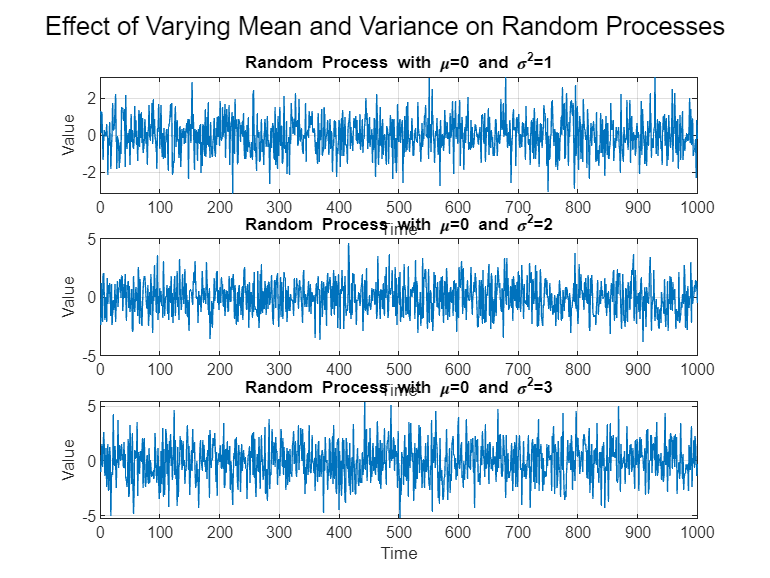

clear all; close all; clc;
% Parameters
num_samples = 1000;  % Number of samples
mean_values = [0, 0, 0];  % Different mean values
variance_values = [1, 2, 3];  % Different variance values

% Generate the time axis (x-axis)
time_axis = 1:num_samples;

% Generate and plot random processes with varying mean and variance
for i = 1:length(mean_values)
    mean_val = mean_values(i);
    sigma = sqrt(variance_values(i));
    
    % Generate random samples from a normal distribution with specified mean and variance
    random_samples = sigma * randn(1, num_samples) + mean_val;

    % Plot the random process
    subplot(length(mean_values), 1, i);
    plot(time_axis, random_samples);
    xlabel('Time');
    ylabel('Value');
    title(['Random Process with \mu=', num2str(mean_val), ' and \sigma^2=', num2str(sigma^2)]);
    grid on;
end

sgtitle('Effect of Varying Mean and Variance on Random Processes');